arc = 0;
new_label = 0;
[sizex,~] = size(arcpoints);
arc_max_label = arcpoints(sizex,1);
num_each_arc = [];
F = zeros(2000,5,120000,'double');
G = zeros(2000,120000,'double');

for i = 1:sizex
    arc_label = arcpoints(i,1);
    if arc~=arc_label
        arc = arc_label;
        new_label = new_label+1;
        num_each_arc(new_label) = 0;
        k = 1;
    end
    F(k,1,new_label) = arcpoints(i,2)*arcpoints(i,3);
    F(k,2,new_label) = arcpoints(i,3)^2;
    F(k,3,new_label) = arcpoints(i,2);
    F(k,4,new_label) = arcpoints(i,3);
    F(k,5,new_label) = 1;
    G(k,new_label) = arcpoints(i,2)^2;
    k = k + 1;
    num_each_arc(new_label) = num_each_arc(new_label) + 1;
end
[~,arc_num] = size(num_each_arc);
sol = zeros(5,arc_num);
for i = 1 : arc_num
    a = F(1:num_each_arc(i),:,i);
    b = G(1:num_each_arc(i),i);
    sol(:,i) = a\b;
end

output = sol(:,sol(1,:).^2-4.*sol(2,:)<0);
[~,out_num] = size(output);
cor = zeros(out_num);
for i = 1 : out_num
    for j = 1 : out_num
        cor(i,j) = Distance(output(:,i),output(:,j));
    end
end
[u,s,v]=svd(cor);
Sam = cor*u(:,1:5);

sums =   675.2832         0         0         0         0         0         0         0         0         0


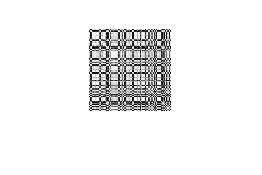

sums =   675.2832  135.7839         0         0         0         0         0         0         0         0


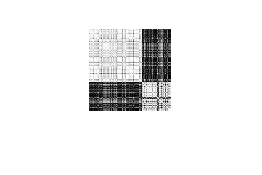

sums =   675.2832  135.7839  113.6853         0         0         0         0         0         0         0


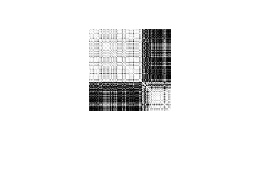

sums =   675.2832  135.7839  113.6853   80.5222         0         0         0         0         0         0


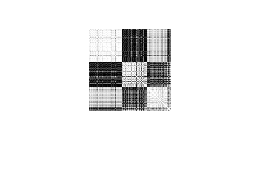

sums =   675.2832  135.7839  113.6853   80.5222   68.8089         0         0         0         0         0


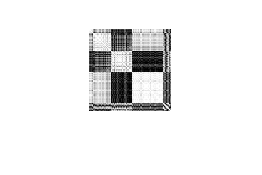

sums =   675.2832  135.7839  113.6853   80.5222   68.8089   55.1847         0         0         0         0


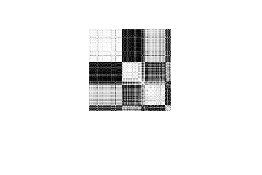

sums =   675.2832  135.7839  113.6853   80.5222   68.8089   55.1847   48.0975         0         0         0


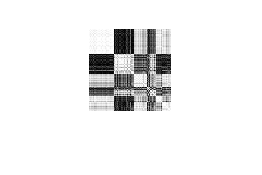

sums =   675.2832  135.7839  113.6853   80.5222   68.8089   55.1847   48.0975   43.5068         0         0


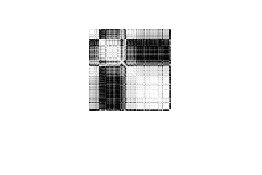

sums =   675.2832  135.7839  113.6853   80.5222   68.8089   55.1847   48.0975   43.5068   36.6564         0


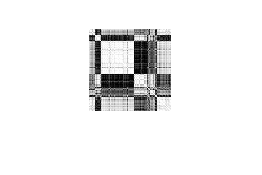

sums =   675.2832  135.7839  113.6853   80.5222   68.8089   55.1847   48.0975   43.5068   36.6564   29.9532


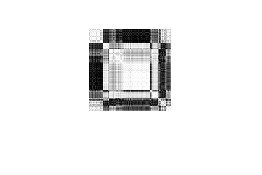

sums = zeros(1,10);
C = {};
id = {};
for j = 1:10
[ind,M,sumd] = kmeans(Sam,j);
[~,I]=sort(ind);
newcor = cor(I,I);
img=mat2gray(newcor);%将数值矩阵X转换为灰度图像
C(j)={M};
id(j)={ind};
sums(j) = sum(sumd)
figure,imshow(img);
end

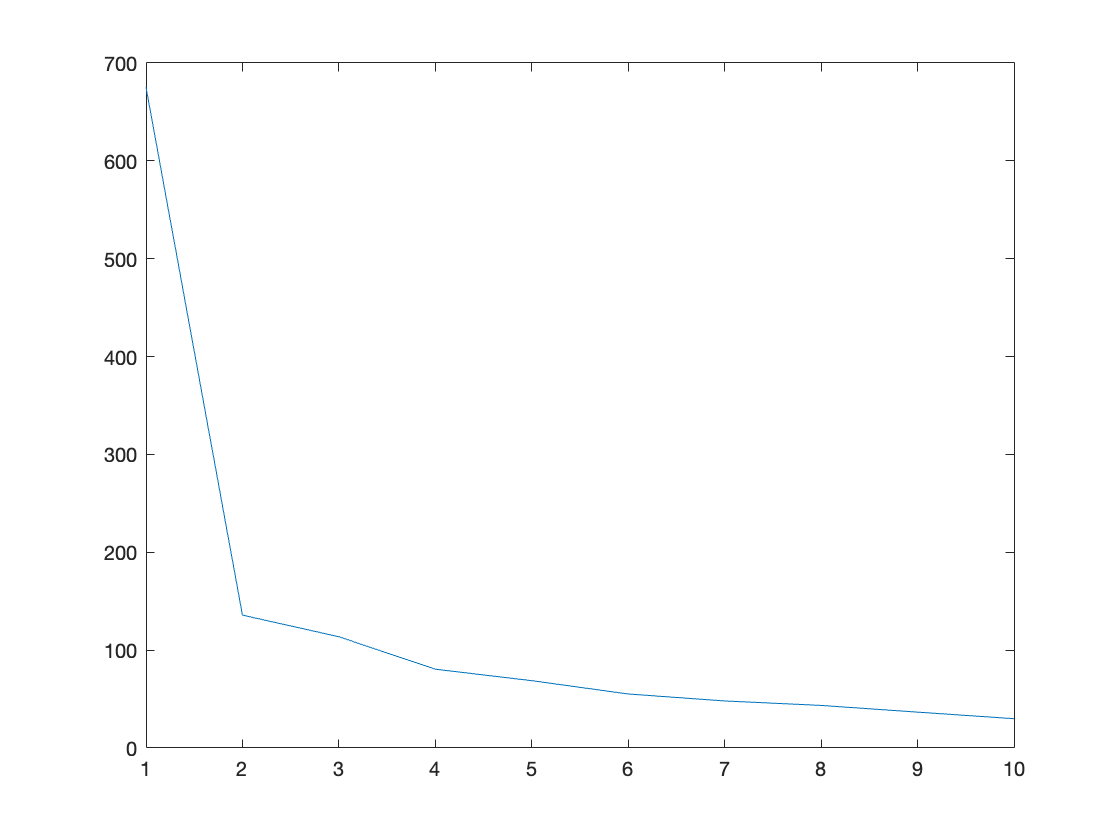

plot(sums)

C

C = 1×10 cell array
    {[-5.2236 -0.6386 0.0574 0.0056 0.0228]}    {2×5 double}    {3×5 double}    {4×5 double}    {5×5 double}    {6×5 double}    {7×5 double}    {8×5 double}    {9×5 double}    {10×5 double}


u(:,1:5)*transpose(C{2})

ans =     0.8708    0.2176
    0.1448    0.7874
    0.1639    0.7807
    0.9044    0.1972
    0.9037    0.1628
    0.9200    0.1949
    0.8508    0.2416
    0.8920    0.1641
    0.9083    0.1786
    0.8734    0.1934


group = id{2}

group =      1
     2
     2
     1
     1
     1
     1
     1
     1
     1


cocl = [];
cocl(:,1)=group-1;
cocl(:,2)=group - 2*cocl(:,1);

conum = [];
conum(1) = sum(cocl(:,1));
conum(2) = sum(cocl(:,2));

arcpoints = load ('hockeyarcpoints.txt','-ascii')

arcpoints =            5         486        1276
           5         485        1275
           5         485        1276
           5         485        1277
           5         486        1275
           5         486        1277
           5         487        1275
           5         487        1276
           5         487        1277
           5         484        1274


[sizex,~] = size(arcpoints);

arc = 0;
new_label = 0;
F = {}
cellArc = {};
for i = 1 : sizex
    arc_label = arcpoints(i,1);
    if arc~=arc_label
        cellArc{arc} = F;
        arc = arc_label;
        new_label = new_label+1;
        F = [];
        k = 1;
    end
    F(k,1) = arcpoints(i,2);
    F(k,2) = arcpoints(i,3);
    F(k,3) = arcpoints(i,1);
    k = k + 1;
end

函数或变量 'F' 无法识别。